## Clustering

Mathilde Marie Duville

Here, an example of clustering is showed. For demonstrative purpose, a partition-based clustering method is detailed, applying a K-means clustering analysis. Partition-based clustering is generally most efficient on medium to large datasets. It produces sphere-like clusters shaped around the centroids.

**Notice 1:** please, run the codes for figures in the command window to output them with a correct scale for visualization

### General concepts

**Notice 2: **Please, refer to the PowerPoint slide dedicated to it for a visual explanation (TheoreticalExplanations.pdf).

The K-means clustering algorithm divided the data into K non-overlaping clusters without needing any internal structure or labelling. Samples within every cluster are similar and between clusters are different. The similarity or dissimilarity between samples is calculated by the distance (*e.g., squared Euclidian, cosine similarity*), based on the input feature for the data. The goal of the K-mean algorithm is to minimize the intra-cluster and maximize the inter-cluster distances.

For instance, if the squared Euclidian distance is chosen, the distance between `x1 and x2` will be defined as the` squared root of the sum between features of the squared difference between x1 and x2. `***Whenever various features are considered, it is necessary to normalize them onto the same scale to avoid applying more weight to spreader-value features.***

After ***determining an a priori number of clusters, ***clusters' centroids are randomly assigned and a distance matrix is calculated, that is the distance between each sample and its assigned centroid. Each sample is assigned to the closest centroid. ***The error can be calculated, that is the sum of the squared distances of each sample from its assigned centroid.*** To minimize the error, centroids are updated to the mean of their cluster, and the distance matrix is computed again. This process is repeated until the centroids no longer move. 

Note that the ***K-means clustering algorithm must be run several times with different random starting conditions*** as each iteration leads to a local optimum, but no necessarily the best possible outcome. 

The ***silhouette value*** can be used to assess the overall accuracy of clusteting. It measures the similarity of every sample with the other samples of same cluster, compared to samples in other clusters. That is `Si`,the silhouette value of the `i``th` sample is defined as the `ratio` between *the *`difference`* between *`bi`*, the minimum average distance from the *`ith`* sample to samples in a different cluster, minimized over the clusters, and *`ai`* that is the average distance from the *`ith`* sample to the other samples in the same cluster as *`i`*,* and the maximum value between a`i` and `bi`. Therefore, the silhouette value is in range [-1 1], where 1 indicates the best clustering option and -1 the worst. ***The silhouette value can be used, for instance, to define the number of clusters.***

### Example with random data

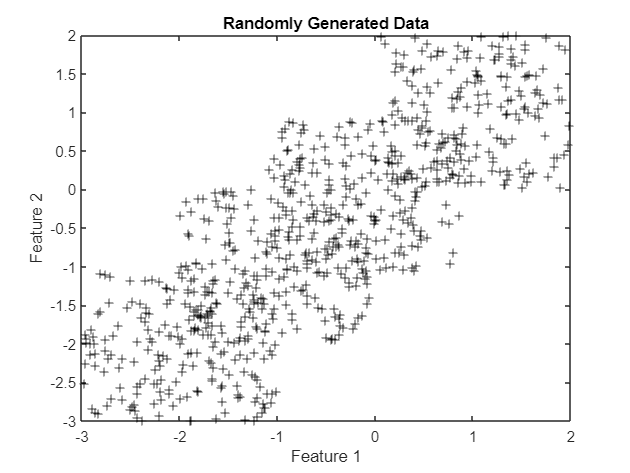

clc; clear; close all;
% Generate data in range -3 2 with 800 samples and 2 features
% Samples are in rows and features in columns
a =-1; b =1; N=200; 
data = [(a + (b-a).*rand(N,2)-ones(N,2)); (a + (b-a).*rand(N,2)+ones(N,2));
    (a + (b-a).*rand(N,2)-(ones(N,2)/10)); (a + (b-a).*rand(N,2)-(ones(N,2)*2)) ];

figure;
plot(data(:,1),data(:,2), '.', 'Color','k', 'LineWidth',0.5, 'Marker','+');
title('Randomly Generated Data');
xlabel('Feature 1'); ylabel('Feature 2')

**Clustering**

Outputs (1) idx: cluster indices (assigment for every sample), (2) C: centroids locations, (3) sumd: error (within-cluster sums of point-to-centroid distances), and (4) D: distance matrix (distances from each point to every centroid).

Here, the K-means clustering algorithm is run 100 times and the solution with the lowest sumd is the final output. The distance metric the the squared of the Euclidian distance, and the initialisation of centroid position is random at each iteration (x100).

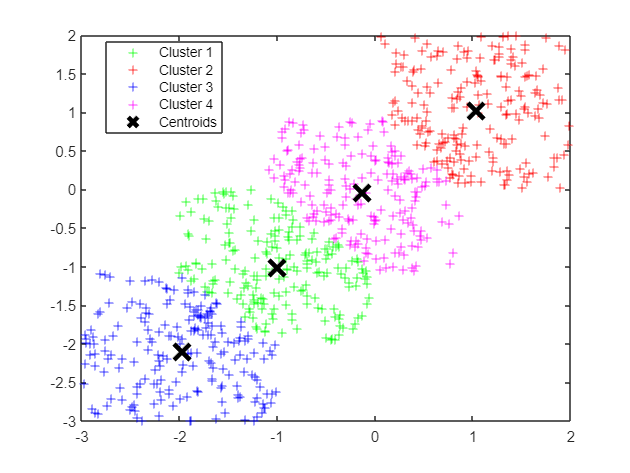

nb_clust = 4;
[idx,C, sumd, D] = kmeans(data, nb_clust, 'Replicates',100, 'Distance','sqeuclidean',...
    'Start','plus');

% Plot clusters with centroids
figure;
colors = {'g', 'r', 'b', 'm'};
for i = 1:1:nb_clust
    %cluster i
    plot(data(idx==i,1),data(idx==i,2), '.', ...
        'Color',colors{i}, 'LineWidth',0.5, 'Marker','+')
    hold on
end
hold on
%centroides
plot(C(:,1),C(:,2),'kx', 'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Cluster 4', 'Centroids', ...
    'Position',[0.171309521731876 0.732936504303463 0.178214287791933 0.165476194109236]);

**Number of clusters: definition by the silhouette value**

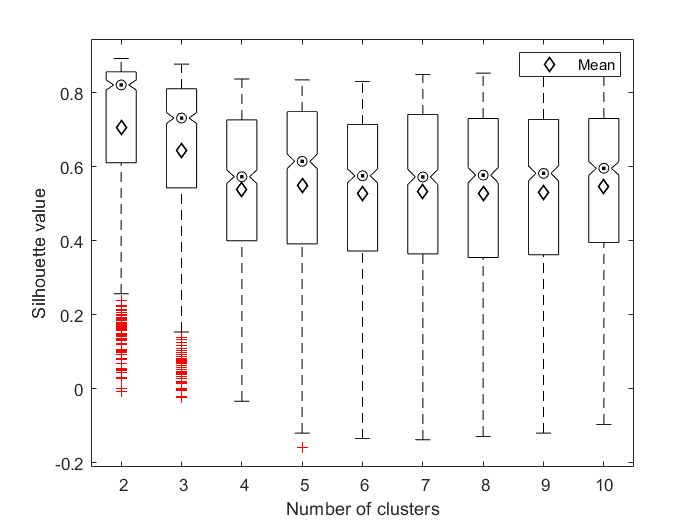

nb_clust = 2:1:10;
idx_tot = cell(1,1); C_tot= cell(1,1); sumd_tot= cell(1,1); D_tot= cell(1,1);
for i = 1:1:length(nb_clust)
    [idx_tot{1,i},C_tot{1,i},sumd_tot{1,i}, D_tot{1,i}] =...
        kmeans(data, nb_clust(i), 'Replicates',100, 'Distance','sqeuclidean',...
        'Start','plus');
    %compute silhouette values based on squared Euclidian distance
    s{1,i} = silhouette(data, idx_tot{1,i}, 'sqEuclidean');
end

% Plot
silhouette_val = []; 
for i = 1:1:size(s,2)
    silhouette_val(:,i) = s{1,i};
end

figure('WindowState','maximized')
boxplot(silhouette_val, 'Notch', 'on', 'Labels',{nb_clust}, 'MedianStyle','target', 'Colors','k');
xlabel("Number of clusters"); ylabel("Silhouette value")
hold on; plot(mean(silhouette_val,1), 'dk','LineWidth',1)
legend('Mean')


best_nb_clust = (find(mean(silhouette_val,1) == max(mean(silhouette_val,1))))+1;

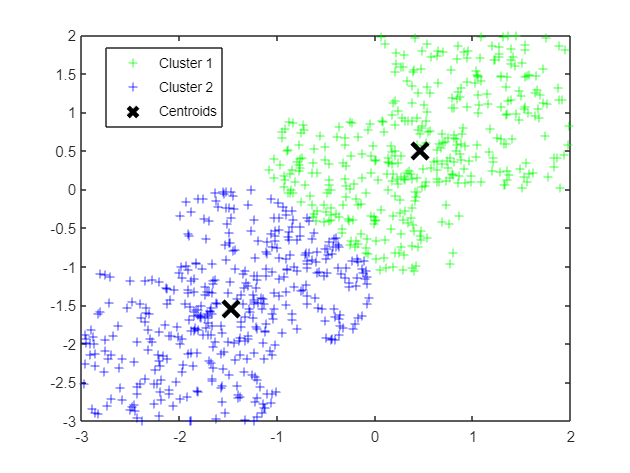

nb_clust = best_nb_clust;
[idx,C, sumd, D] = kmeans(data, nb_clust, 'Replicates',100, 'Distance','sqeuclidean',...
    'Start','plus');

% Plot clusters with centroids
figure;
colors = {'g', 'b'};
for i = 1:1:nb_clust
    %cluster i
    plot(data(idx==i,1),data(idx==i,2), '.', ...
        'Color',colors{i}, 'LineWidth',0.5, 'Marker','+')
    hold on
end
hold on
%centroides
plot(C(:,1),C(:,2),'kx', 'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1', 'Cluster 2','Centroids', ...
    'Position',[0.171309521731876 0.732936504303463 0.178214287791933 0.165476194109236]);

### Assign new data to generated clusters

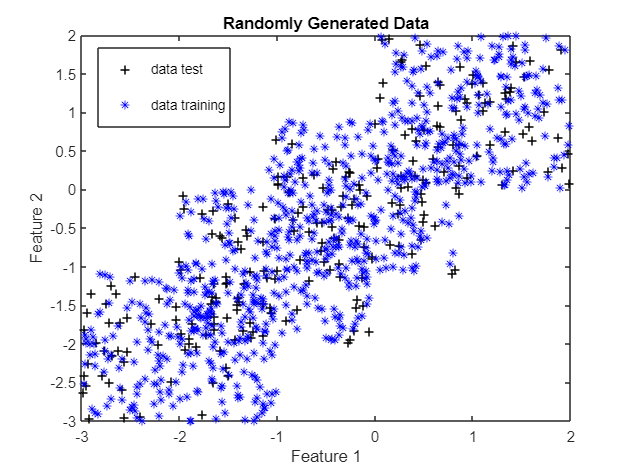

% Generate test data in range -3 2 with 240 samples and 2 features
% Samples are in rows and features in columns
a =-1; b =1; N=60; 
data_test = [(a + (b-a).*rand(N,2)-ones(N,2)); (a + (b-a).*rand(N,2)+ones(N,2));
    (a + (b-a).*rand(N,2)-(ones(N,2)/10)); (a + (b-a).*rand(N,2)-(ones(N,2)*2)) ];

figure;
plot(data_test(:,1),data_test(:,2), '.', 'Color','k', 'LineWidth',1, 'Marker','+');
title('Randomly Generated Data');
hold on 
plot(data(:,1),data(:,2), '.', 'Color','b', 'LineWidth',0.5, 'Marker','*');
xlabel('Feature 1'); ylabel('Feature 2')
legend('data test','data training', 'Position',[0.171309521731876 0.732936504303463 0.178214287791933 0.165476194109236])

Compute the pairwise distance between two sets of observations

Outputs (1) dist_pairwise: distance between each pair of observations in the test data and the centroids using the sqaured Euclidian distance. Only the smallest distance to centroids is returned (i.e., the nearest centroid to the testing data). (2) idx_test: index of the centroid that correspond to the smallest distance from every sample of the testing data.  

Inputs: distance metric: squared Euclidian distance, and only the nearest centroid (smallest distance and 1 value).

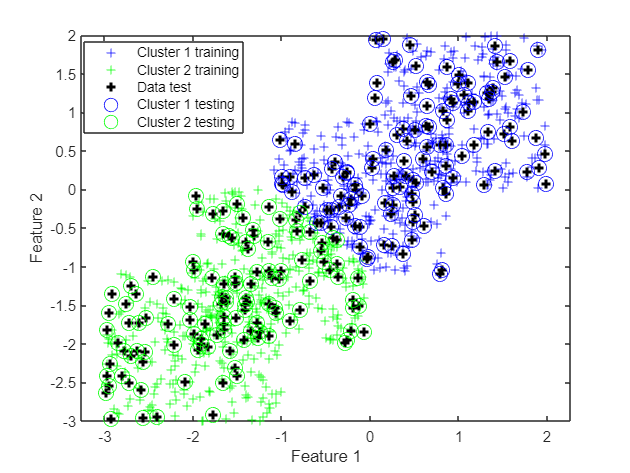

[dist_pairwise,idx_test] = pdist2(C,data_test,'squaredeuclidean','Smallest',1);

% Extract data assigned to cluster 1
data_test_cluster1 = data_test(idx_test==1,:);
% Indices within testing data
idx_data_test_cluster1 = find(idx_test==(idx_test==1))';


% Extract data assigned to cluster 2
data_test_cluster2 = data_test(idx_test==2,:);
% Indices within testing data
idx_data_test_cluster2 = find(idx_test==(idx_test==2))';

% Plot results
figure('WindowState','maximized')
gscatter(data(:,1),data(:,2),idx,'bg','++')
hold on 
plot(data_test(:,1),data_test(:,2), '.', 'Color','k', 'LineWidth',2, 'Marker','+');
hold on 
gscatter(data_test(:,1),data_test(:,2),idx_test','bg','o', 10)
xlabel('Feature 1'); ylabel('Feature 2')
legend('Cluster 1 training','Cluster 2 training', 'Data test',...
    'Cluster 1 testing','Cluster 2 testing',...
    'Position',[0.171309521731876 0.732936504303463 0.178214287791933 0.165476194109236])